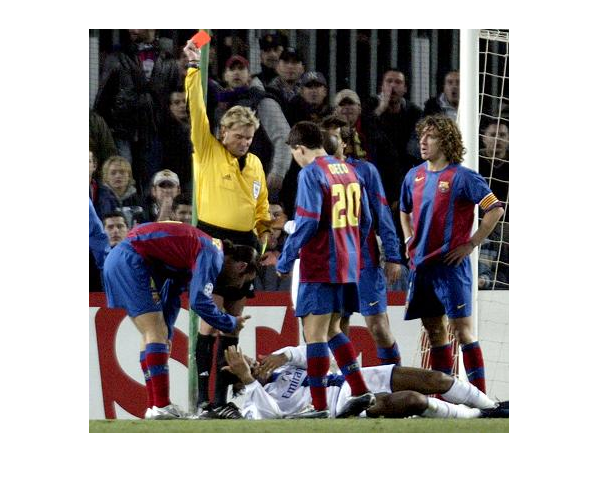

im = imread("LAB 1 - Soccer\barcelona\01.jpg");
imshow(im);

f = size(im,1);
c = size(im,2);


## Crear histograma

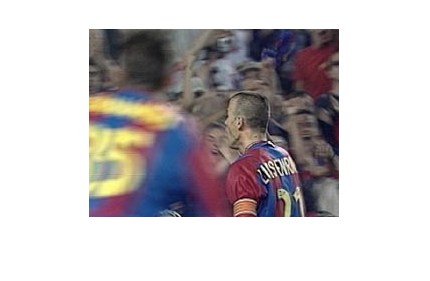

im = imread("LAB 1 - Soccer\barcelona\15.jpg");
imshow(im);

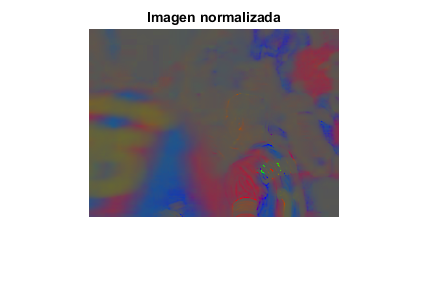

f = size(im,1);
c = size(im,2);

r=im(:,:,1);
g=im(:,:,2);
b=im(:,:,3);
I=double(r)+double(g)+double(b);
rn=double(r)./I;
gn=double(g)./I;
bn=double(b)./I;
rgbNorm=cat(3,rn,gn,bn);
figure,imshow(rgbNorm),title('Imagen normalizada');

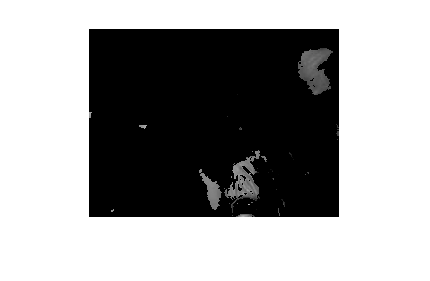

contR=0;
imFilter = uint8(zeros(f,c));
imFilter2 = uint8(zeros(f,c));
imFilter3 = uint8(zeros(f,c));
for i=1:f
    for j=1:c
        if rn(i,j) > 0.50
            imFilter(i,j)=im(i,j,1);
            contR=contR+1;
        end
        if gn(i,j) > 0.50
            imFilter2(i,j)=im(i,j,2);
        end
        if bn(i,j) > 0.50
            imFilter3(i,j)=im(i,j,3);
        end
    end
end
imshow(imFilter)

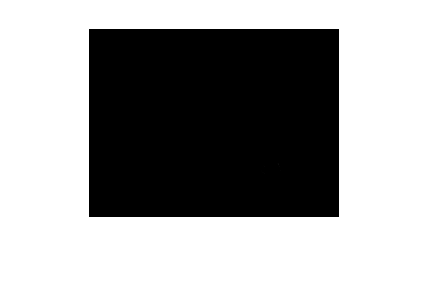

imshow(imFilter2)

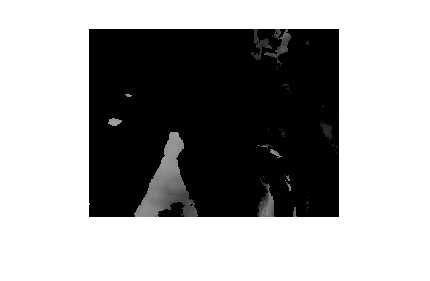

imshow(imFilter3)

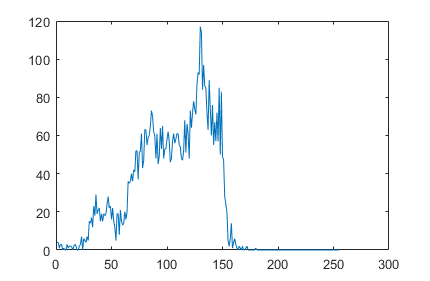

filtrado=cat(3,imFilter,imFilter2,imFilter3);
k = imhist(filtrado);
subk = k(2:256);
plot(subk);

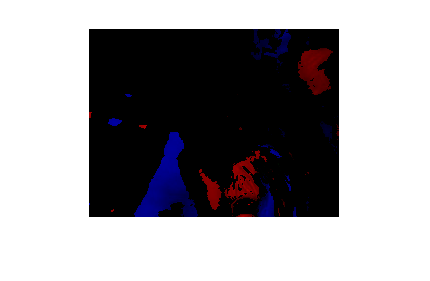

imshow(cat(3,imFilter,imFilter2,imFilter3))

imshow(im);


contR/(f*c)

ans = 0.0521

## Histograma colores separados

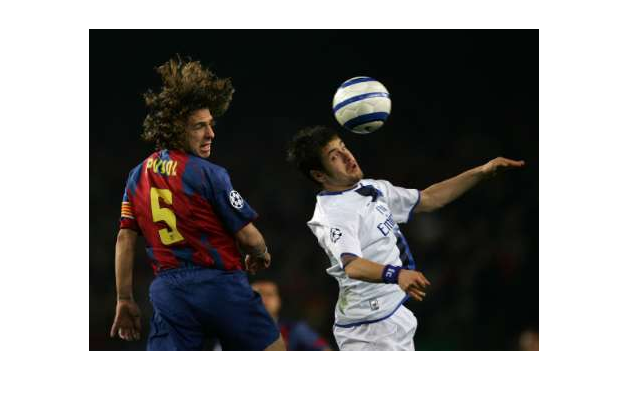




figure
imshow(im);

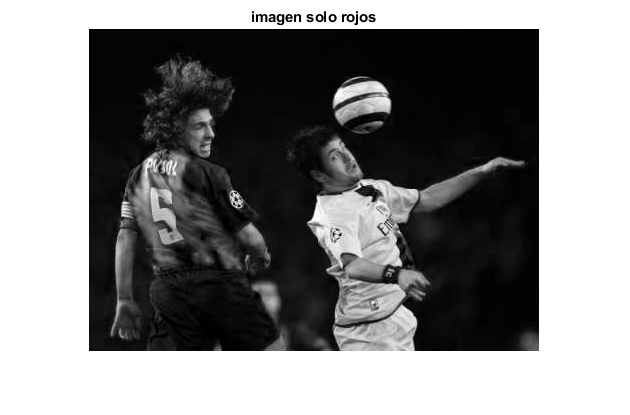

imshow(r),title('imagen solo rojos');

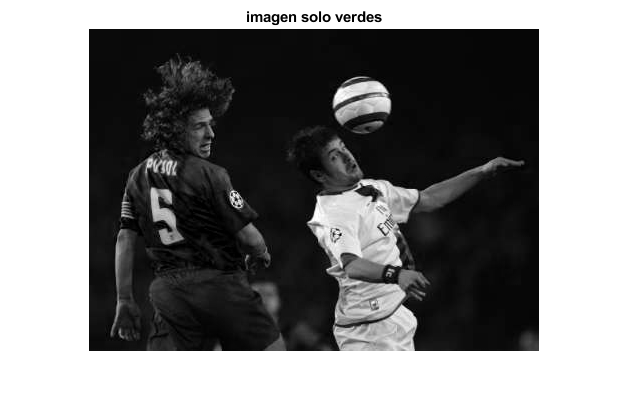

imshow(g);title('imagen solo verdes');

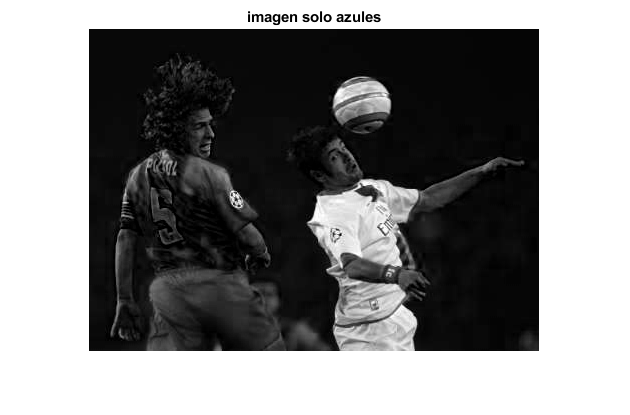

imshow(b);title('imagen solo azules');

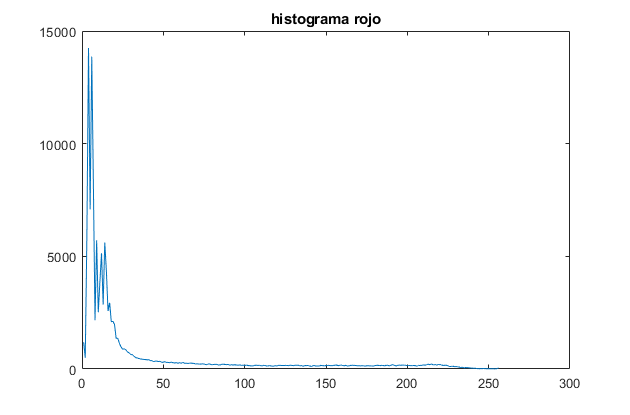

rh = imhist(r);
gh = imhist(g);
bh = imhist(b);
plot(rh),title('histograma rojo');

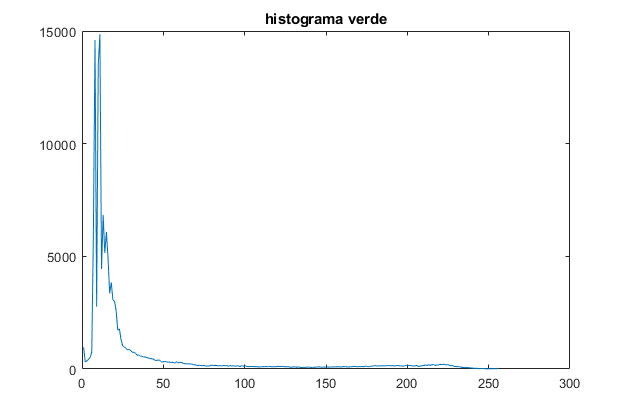

plot(gh),title('histograma verde');

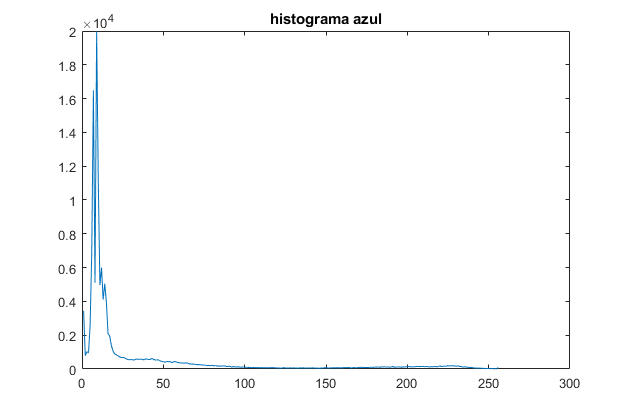

plot(bh),title('histograma azul');

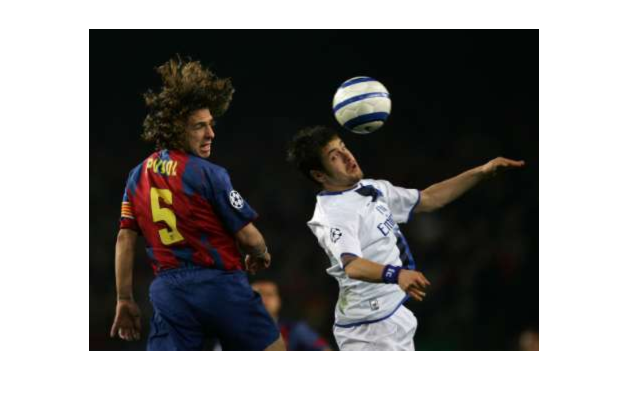



suav=imgaussfilt(im);
imshow(suav);

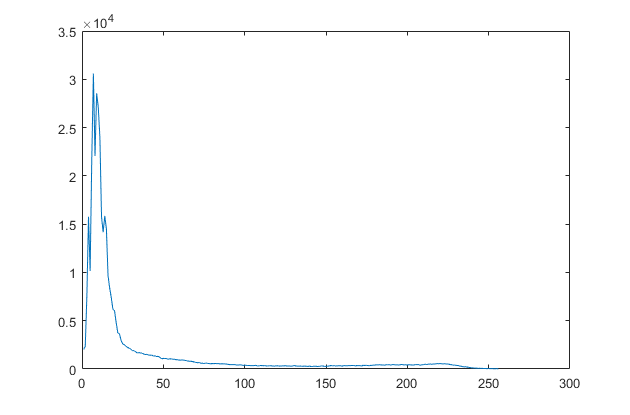

plot(imhist(suav));

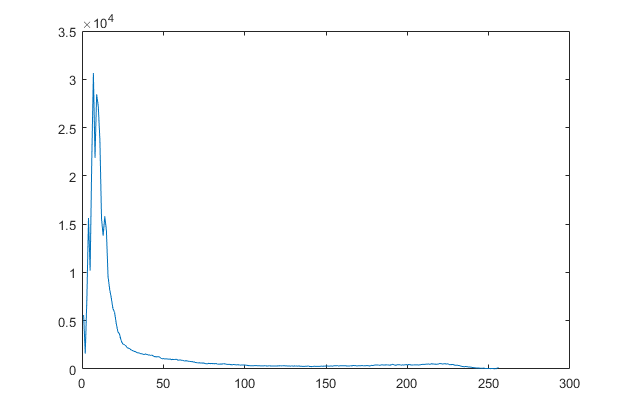

plot(imhist(im));